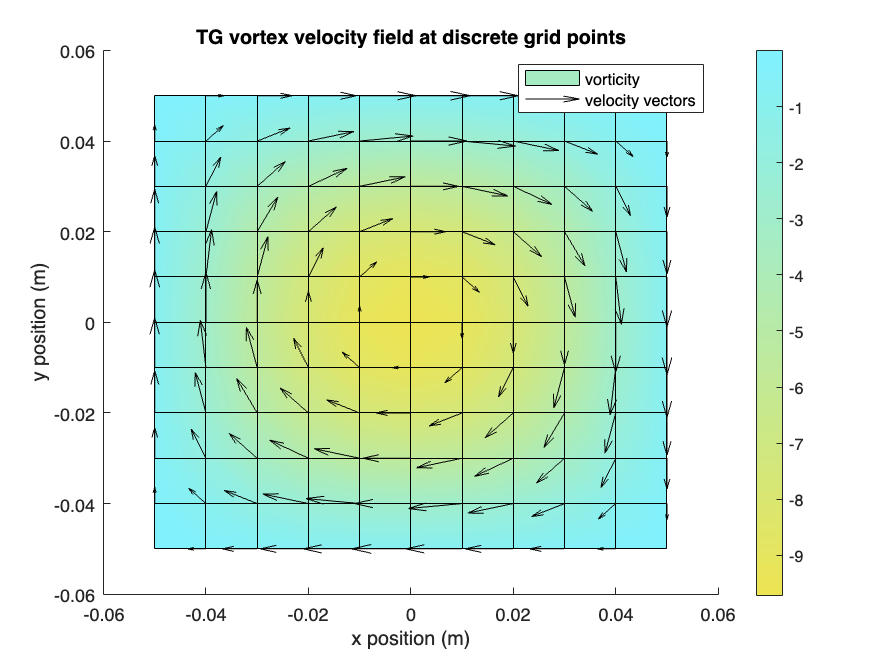

A_TG = 0.005; % Amplitude of the TG vortex, in m^2/s
L_TG = 0.1; % Length of the TG vortex, in m
n_step = 10;
[X,Y] = meshgrid(-L_TG / 2 : L_TG / n_step : L_TG / 2);
psi_TG = -A_TG*cos(pi * X / L_TG) .* cos(pi * Y / L_TG);

vfx_disc = (A_TG * pi / L_TG) * cos(pi * X / L_TG) .* sin(pi * Y / L_TG);
vfy_disc = -(A_TG * pi / L_TG) * sin(pi * X / L_TG) .* cos(pi * Y / L_TG);

figure
hold on
[curlz,cav] = curl(X, Y, vfx_disc, vfy_disc);
c = pcolor(X, Y, curlz);
c.FaceColor = 'interp';

% Define two colors for the gradient (e.g., from red to blue)
% color1 = [0 0.4470 0.7410]; %  (RGB)
color1 = [0.9290 0.8940 0.3250];
color2 = [0.5010 0.9450 1]; %  (RGB)

% Create a custom colormap with a smooth transition between these two colors
numColors = 128; % Number of colors in the colormap
cmap = [linspace(color1(1), color2(1), numColors)' ...
        linspace(color1(2), color2(2), numColors)' ...
        linspace(color1(3), color2(3), numColors)'];

colormap(cmap);
colorbar;

q = quiver(X, Y, vfx_disc, vfy_disc, 'k');
title('TG vortex velocity field at discrete grid points')
xlabel('x position (m)')
ylabel('y position (m)')
legend({'vorticity','velocity vectors'})